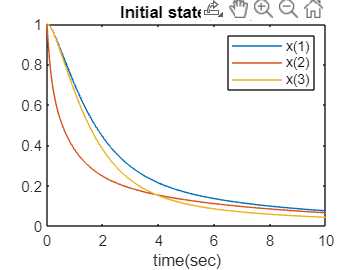

%Simulating the results

tstart = 0;
tend = 10;
dt = 0.01;
n = 1000;

tspan = transpose(linspace(tstart,tend,n));
xinit = [1 1 1]; %initial values of states

[t,x] = ode45(@integratingfunc_SpringMass_system, tspan, xinit);
plot(t,x(:,1),t,x(:,2),t,x(:,3));
title("Initial state(1,1,1)")
legend(["x(1)","x(2)","x(3)"])
xlabel("time(sec)")

function dxdt = integratingfunc_SpringMass_system(t,x)
%INTEGRATINGFUNC_SPRINGMASS_SYSTEM Summary of this function goes here
%   Detailed explanation goes here

K = [1 3 3];              %Gain
z(1) = (-x(1)*x(1)/2)+(x(3));            %Normalized state coordinate
z(2) = (x(1)^2) + x(1) - (2*(x(3)));
z(3) = (-2*x(1)*x(1))-(3*x(1))+(x(2))+(4*x(3));
n = (x(1)*((2*(x(1)+x(2)))-x(3)+8))-(4*x(2))-(8*x(3));  %n(x)

%Input:
u = n - ((K(1)*z(1))+(K(2)*z(2))+(K(3)*z(3)));

dxdt = zeros(3,1);
dxdt(1) = (-x(1)) + x(2);
dxdt(2) =  x(1)-x(2)-(x(1)*x(3))+u;
dxdt(3) = x(1) + (x(1)*x(2)) - (2*x(3));
end